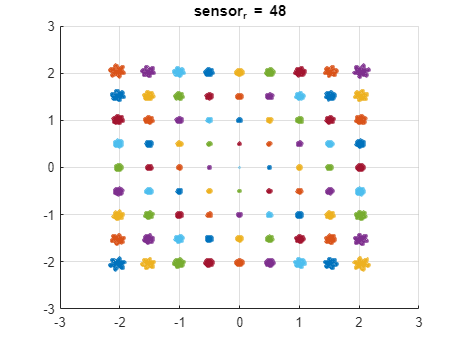

%% Loading data
clc;
clear;
close all;

load("xytheta_output_sensor_r48_kg3247_20220623_1753.mat")

x1 = x_mid+2;
y0 = y_mid;
date = datestr(now,'yyyymmdd_HHMM');
theta_check = theta_elec;

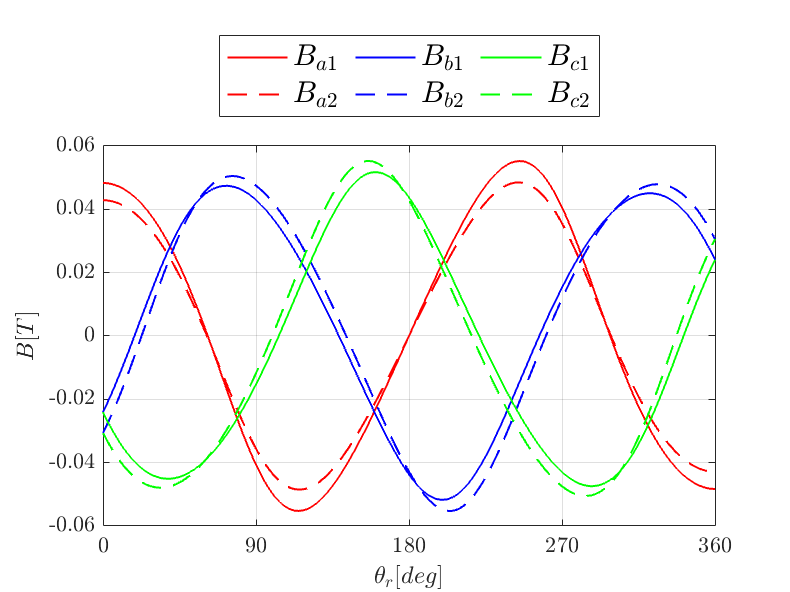


%% getting abc1 abc2 and its corresponding dq
a1_1 = a1(:,x_mid+2,y_mid)';
a2_1 = a2(:,x_mid+2,y_mid)';
b1_1 = b1(:,x_mid+2,y_mid)';
b2_1 = b2(:,x_mid+2,y_mid)';
c1_1 = c1(:,x_mid+2,y_mid)';
c2_1 = c2(:,x_mid+2,y_mid)';

alpha1_1 = alpha(1,:,x_mid+2,y_mid)';
alpha2_1 = alpha(2,:,x_mid+2,y_mid)';
beta1_1 = beta(1,:,x_mid+2,y_mid)';
beta2_1 = beta(2,:,x_mid+2,y_mid)';
gamma1_1 = gamma(1,:,x_mid+2,y_mid)';
gamma2_1 = gamma(2,:,x_mid+2,y_mid)';

x_position(1,x_mid+1);

%% abc1 abc2 plot
figure_abc12 = figure;
hold on;
grid on;

ax = gca;
xticks([0 90 180 270 360])
ax.TickLabelInterpreter='latex';
xlim([0,360])
plot(theta_check,a1_1,'-r','LineWidth',1)
plot(theta_check,a2_1,'--r','LineWidth',1)
plot(theta_check,b1_1,'-b','LineWidth',1)
plot(theta_check,b2_1,'--b','LineWidth',1)
plot(theta_check,c1_1,'-g','LineWidth',1)
plot(theta_check,c2_1,'--g','LineWidth',1)
hold off;
box on;
ylatex = '$B[T]$';
ylabel(ylatex,'Interpreter','latex')
xlatex = '${\theta}_r[deg]$';
xlabel(xlatex,'Interpreter','latex')

leg_abc = legend('$B_{a1}$','$B_{a2}$','$B_{b1}$','$B_{b2}$','$B_{c1}$','$B_{c2}$','Location','northoutside','Numcolumns',3);
set(leg_abc, 'Interpreter', 'latex');
set(leg_abc, 'FontSize', 15);

filename = sprintf('abc1abc2_sensor_r%d_%s.png',sensor_r,date);
saveas(figure_abc12,filename,'png')

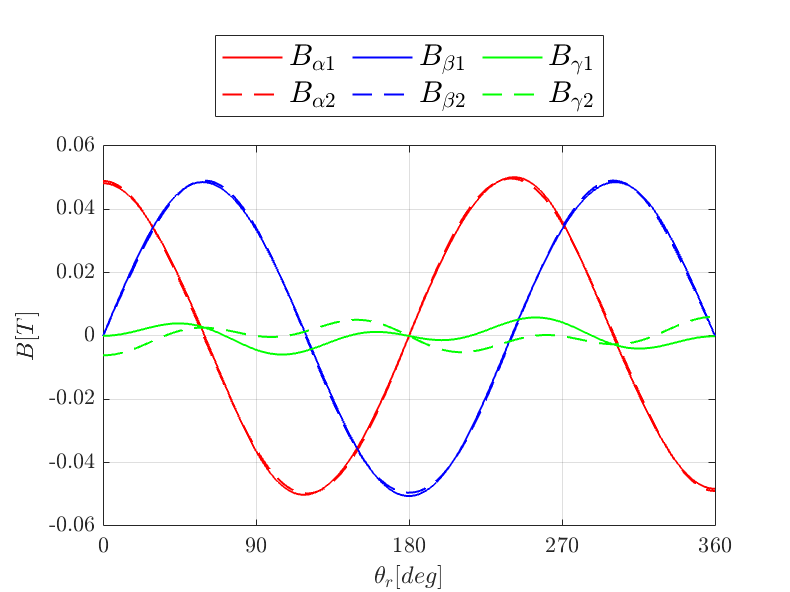

%% alpha beta gamma 1, 2
figure_alpha = figure;
hold on;
grid on;

ax = gca;
xticks([0 90 180 270 360])
ax.TickLabelInterpreter='latex';
xlim([0,360])
plot(theta_check,alpha1_1,'-r','LineWidth',1)
plot(theta_check,alpha2_1,'--r','LineWidth',1)
plot(theta_check,beta1_1,'-b','LineWidth',1)
plot(theta_check,beta2_1,'--b','LineWidth',1)
plot(theta_check,gamma1_1,'-g','LineWidth',1)
plot(theta_check,gamma2_1,'--g','LineWidth',1)
hold off;
box on;
ylatex = '$B[T]$';
ylabel(ylatex,'Interpreter','latex')
xlatex = '${\theta}_r[deg]$';
xlabel(xlatex,'Interpreter','latex')

leg_abc = legend('$B_{\alpha1}$','$B_{\alpha2}$','$B_{\beta1}$','$B_{\beta2}$','$B_{\gamma1}$','$B_{\gamma2}$','Location','northoutside','Numcolumns',3);
set(leg_abc, 'Interpreter', 'latex')
set(leg_abc, 'FontSize', 15);

filename2 = sprintf('alphabetagamma_sensor_r%d_%s.png',sensor_r,date);
saveas(figure_alpha,filename2,'png');

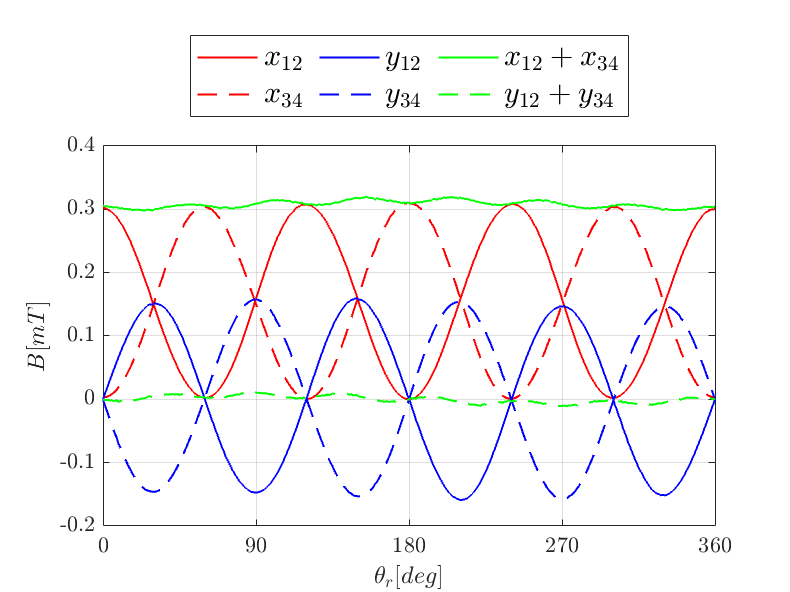

%% x12,y12,x34,y34
x12_x1y0= 1000*x12(:,x_mid+2,y_mid);
x34_x1y0= 1000*x34(:,x_mid+2,y_mid);
y12_x1y0= 1000*y12(:,x_mid+2,y_mid);
y34_x1y0= 1000*y34(:,x_mid+2,y_mid);

x12x34_x1y0 = x12_x1y0+x34_x1y0;
y12y34_x1y0 = y12_x1y0+y34_x1y0;

figure_x12x34 = figure;
hold on;
grid on;

ax = gca;
xticks([0 90 180 270 360])
ax.TickLabelInterpreter='latex';
xlim([0,360]);
plot(theta_check,x12_x1y0,'-r','LineWidth',1)
plot(theta_check,x34_x1y0,'--r','LineWidth',1)
plot(theta_check,y12_x1y0,'-b','LineWidth',1)
plot(theta_check,y34_x1y0,'--b','LineWidth',1)
plot(theta_check,x12x34_x1y0,'-g','LineWidth',1)
plot(theta_check,y12y34_x1y0,'--g','LineWidth',1)
hold off;
box on;
ylatex = '$B[mT]$';
ylabel(ylatex,'Interpreter','latex')
xlatex = '${\theta}_r[deg]$';
xlabel(xlatex,'Interpreter','latex')

leg_abc = legend('$x_{12}$','$x_{34}$','$y_{12}$','$y_{34}$','$x_{12}+x_{34}$','$y_{12}+y_{34}$','Location','northoutside','Numcolumns',3);
set(leg_abc, 'Interpreter', 'latex')
set(leg_abc, 'FontSize', 15);

filename = sprintf('x12x34y12y34_sensor_r%d_%s.png',sensor_r,date);
saveas(figure_x12x34,filename,'png');

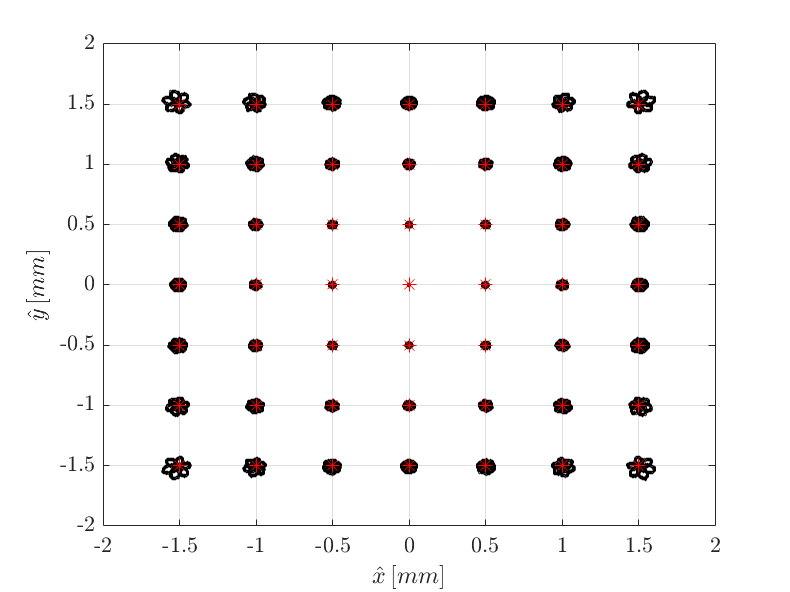

%% full figure
full_figure = figure;
hold on;
grid on;
ax = gca;
ax.TickLabelInterpreter='latex';
% title(['sensor_r = ',num2str(sensor_r)])
xlim([min(x_position),max(x_position)])
ylim([min(y_position),max(y_position)])
x_index2=x_index;
y_index2=y_index;
x_index2(:,1)=[];
x_index2(:,end)=[];
y_index2(:,1)=[];
y_index2(:,end)=[];
for m = x_index2
    for n = y_index2
        scatter(xhat(:,m,n),yhat(:,m,n),2,'black')
    end
end
mesh_x = -1.5:0.5:1.5;
mesh_y = -1.5:0.5:1.5;
[X Y] = meshgrid(mesh_x,mesh_y);
scatter(X, Y,30,'red','*');
box on

ylatex = '$\hat{y}\,[mm]$';
ylabel(ylatex,'Interpreter','latex')
xlatex = '$\hat{x}\,[mm]$';
xlabel(xlatex,'Interpreter','latex')
hold off

filename = sprintf('xy_total_sensor_r%d_%s.png',sensor_r,date);
saveas(full_figure,filename);

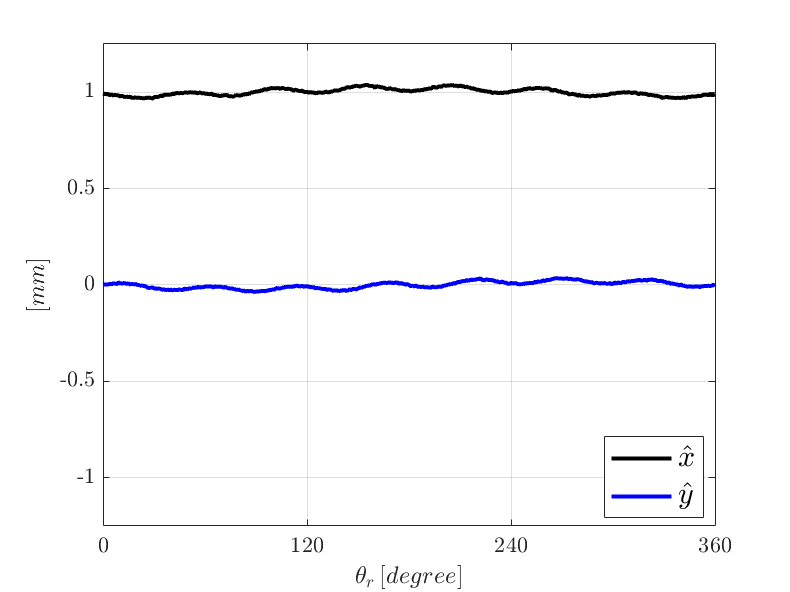

%% x=1 y=0


xhat1 = xhat(:,x1,y0);
yhat0 = yhat(:,x1,y0);


figx1y0 = figure;
hold on;
ax = gca;
xticks([0 90 180 270 360])
ax.TickLabelInterpreter='latex';
plot(theta_check,xhat1,'k','Linewidth',2)
plot(theta_check,yhat0,'b','Linewidth',2)
leg_10 = legend('$\hat{x}$','$\hat{y}$','Location','best');
set(leg_10, 'Interpreter', 'latex');
set(leg_10, 'FontSize', 15);
grid on
box on
xlim([0 360])
xticks([0 120 240 360])
ylim([-1.25 1.25])
ylatex = '$[mm]$';
ylabel(ylatex,'Interpreter','latex')
xlatex = '$\theta_r\,[degree]$';
xlabel(xlatex,'Interpreter','latex')
hold off

filename = sprintf('x1y0_partial_sensor_r%d_%s.png',sensor_r,date);
saveas(figx1y0,filename,'png')

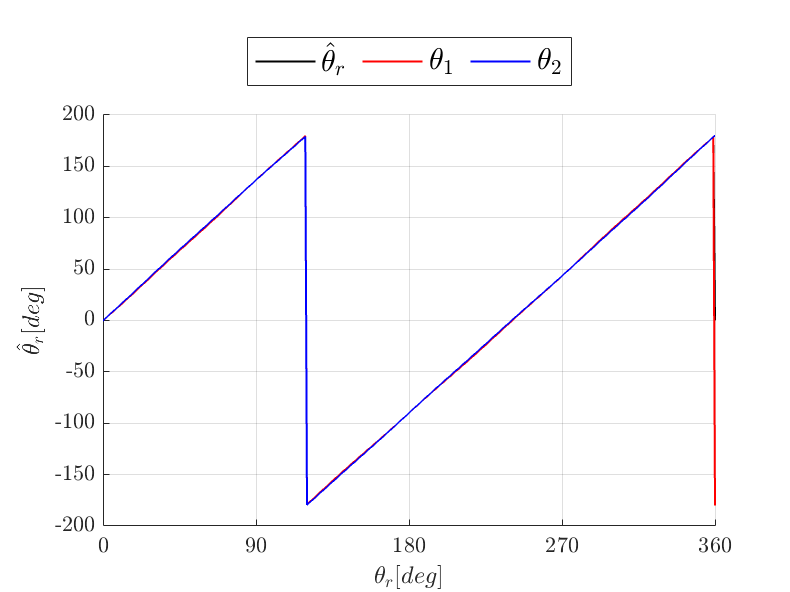


%% theta estimation

theta1_hatx1y0 = theta1hat(:,x1,y0)*180/pi();
theta1_hatx1y0 = theta1_hatx1y0.';
theta2_hatx1y0 = theta2hat(:,x1,y0)*180/pi();
theta2_hatx1y0 = theta2_hatx1y0.';
theta_hatx1y0 = theta_r_hat(:,x1,y0)*180/pi();
theta_hatx1y0 = theta_hatx1y0.';
theta_in_elecx1y0 = zeros(1,length(theta_r_in));
for i = theta_r_index
    if(theta_r_in(1,i)>90)
        theta_in_elecx1y0(1,i)=2*(theta_r_in(1,i)-180);
    else
        theta_in_elecx1y0(1,i)=2*theta_r_in(1,i);
    end
end
figure_theta = figure;
hold on;
grid on;

ax = gca;
xticks([0 90 180 270 360])
ax.TickLabelInterpreter='latex';

plot(theta_elec,theta_hatx1y0,'k','LineWidth',1)
plot(theta_elec,theta1_hatx1y0,'r','LineWidth',1)
plot(theta_elec,theta2_hatx1y0,'b','LineWidth',1)
ylim([-200 200])
xlim([0 360])
hold off;
ylatex = '$\hat{\theta}_r[deg]$';
ylabel(ylatex,'Interpreter','latex')
xlatex = '${\theta}_r[deg]$';
xlabel(xlatex,'Interpreter','latex')

leg_abc = legend('$\hat{\theta}_r$','${\theta}_1$','${\theta}_2$','Location','northoutside','Numcolumns',3);
set(leg_abc, 'Interpreter', 'latex')
set(leg_abc, 'FontSize', 15);

filename = sprintf('theta_x1y0_sensor_r%d_%s.png',sensor_r,date);
saveas(figure_theta,filename,'png');


%% theta err estimation

figure_err_theta = figure;
hold on;
grid on;

ax = gca;
xticks([0 90 180 270 360])
ax.TickLabelInterpreter='latex';

theta_err1 = theta1_hatx1y0-theta_in_elecx1y0;
theta_err2 = theta2_hatx1y0-theta_in_elecx1y0;
theta_err = theta_hatx1y0-theta_in_elecx1y0;



err_index1 = abs(theta_err1)>30

err_index1 = 1×361 logical 배열
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


err_index2 = abs(theta_err2)>30

err_index2 = 1×361 logical 배열
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


err_index = abs(theta_err)>30

err_index = 1×361 logical 배열
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


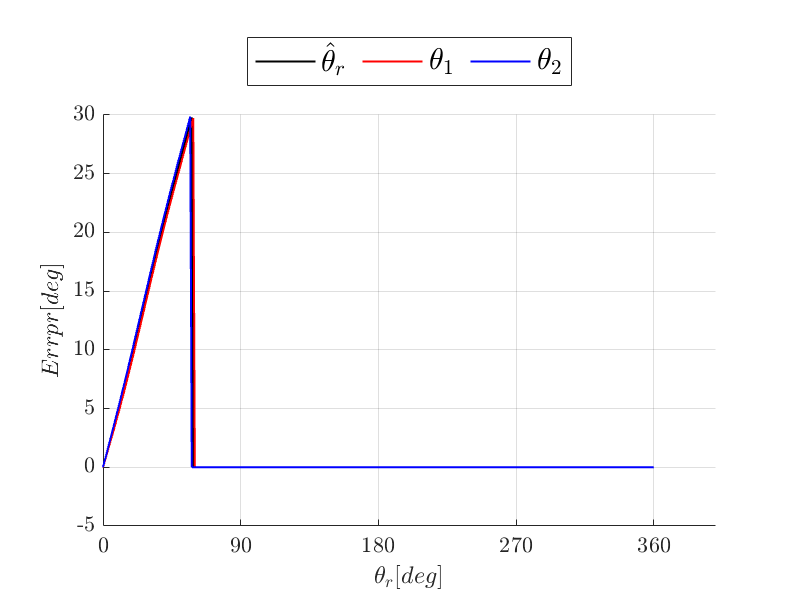

theta_err1(err_index1)=0;
theta_err2(err_index2)=0;
theta_err(err_index)=0;


plot(theta_elec,theta_err,'k','LineWidth',1);
plot(theta_elec,theta_err1,'r','LineWidth',1);
plot(theta_elec,theta_err2,'b','LineWidth',1);

hold off;
ylatex = '$Errpr[deg]$';
ylabel(ylatex,'Interpreter','latex')
xlatex = '${\theta}_r[deg]$';
xlabel(xlatex,'Interpreter','latex')

leg_abc = legend('$\hat{\theta}_r$','${\theta}_1$','${\theta}_2$','Location','northoutside','Numcolumns',3);
set(leg_abc, 'Interpreter', 'latex')
set(leg_abc, 'FontSize', 15);

filename = sprintf('theta_err_x1y0_sensor_r%d_%s.png',sensor_r,date);
saveas(figure_err_theta,filename,'png')

figure
plot(theta1hat(:,1,1))